%Selection of Data from Database , 70% for Training and 30% for testing

clear;clc;


imds = imageDatastore('E:\flower Project\P_Processed\', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              'E:\flower Project\P_Processed\image00001.jpg';
                              'E:\flower Project\P_Processed\image00013.jpg';
                              'E:\flower Project\P_Processed\image00014.jpg'
                               ... and 6 more
                              }
                      Labels: [P_Processed; P_Processed; P_Processed ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage



numImages = numel(imds.Labels);


for i = 1:numImages
    I{i} = readimage(imds,i);
end

%figure
%imshow(imtile(I))
%% 
% Feature Extraction using GLCM and Red, Green , Blue average density

 [ TestSet] = FeatureExtractorFunctionNew(imds)

TestSet = 9×10 table
    Contrast    Correlation    Energy     Homogenity      Red       stdr      green      stdg      blue       stdb 
    ________    ___________    _______    __________    _______    ______    _______    ______    _______    ______

    0.45638        0.8909      0.43908     0.91707      0.61959     67.28    0.23124    29.575    0.52972     60.86
    0.31392       0.95177      0.42292      0.9368      0.86229    60.689    0.33502    27.325    0.34993    30.682
    0.85552         0.933      0.46259     0.92536      0.70155    45.125    0.70338    45.813    0.69952     53.46
    0.48568        0.9503      0.42688     0.95032       0

% [ TestSet] = FeatureExtractorFunction(imdsTest);
 load trainedclassifier
 YPred = trainedClassifier.predictFcn(TestSet)

YPred = 9×1 categorical array
     11 
     12 
     1 
     15 
     10 
     7 
     10 
     23 
     1 


load FlowerNet
augimds = augmentedImageDatastore([227 227 3],imds);
YPred = classify(FlowerNet,augimds)

YPred = 9×1 categorical array
     20 
     25 
     26 
     20 
     1 
     7 
     19 
     7 
     11 


%% 



queryno = 2;
BucketSize=10;
foldername = strcat('E:\flower Project\FLR_IMGS\',char(YPred(queryno)))

foldername = 'E:\flower Project\FLR_IMGS\25'

imdsDatabase = imageDatastore(foldername)

imdsDatabase =   ImageDatastore with properties:

                       Files: {
                              'E:\flower Project\FLR_IMGS\25\image00001.jpg';
                              'E:\flower Project\FLR_IMGS\25\image00002.jpg';
                              'E:\flower Project\FLR_IMGS\25\image00003.jpg'
                               ... and 97 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


[ TrainingSet] = FeatureExtractorFunctionNew(imdsDatabase)


TrainingSet =

  0×10 empty table



[ TestSet] = FeatureExtractorFunctionNew(imds);
%% 
% *KD Tree Algorithm code Implementation*
% 
% *( |*'chebychev','cityblock','euclidean','minkowski')|

TrainData=table2array(TrainingSet);
TestData=table2array(TestSet);
%% 
% |'minkowski' - method|

Mdl = KDTreeSearcher(TrainData,'Distance','minkowski','BucketSize',BucketSize)

Mdl =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'minkowski'
    DistParameter: 2
                X: [0×10 double]


IdxNN = knnsearch(Mdl,TestData(queryno,:),'K',8)


IdxNN =

  1×0 empty double row vector



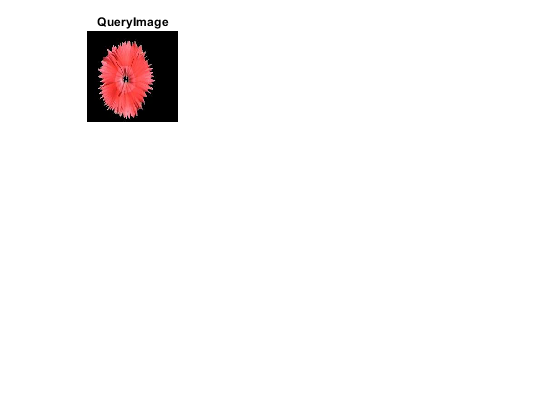


figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

    
%% 
% |'euclidean' - method|

Md2 = KDTreeSearcher(TrainData,'Distance','euclidean','BucketSize',BucketSize)

Md2 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'euclidean'
    DistParameter: []
                X: [0×10 double]


IdxNN = knnsearch(Md2,TestData(queryno,:),'K',8)


IdxNN =

  1×0 empty double row vector




figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

    
    
%% 
% |'cityblock' - method|

Md3 = KDTreeSearcher(TrainData,'Distance','cityblock','BucketSize',BucketSize)

Md3 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'cityblock'
    DistParameter: []
                X: [0×10 double]


IdxNN = knnsearch(Md3,TestData(queryno,:),'K',8)


IdxNN =

  1×0 empty double row vector




figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')

    
    
%% 
% |'chebychev' - method|

Md4 = KDTreeSearcher(TrainData,'Distance','chebychev','BucketSize',BucketSize)

Md4 =   KDTreeSearcher with properties:

       BucketSize: 10
         Distance: 'chebychev'
    DistParameter: []
                X: [0×10 double]


IdxNN = knnsearch(Md4,TestData(queryno,:),'K',8)


IdxNN =

  1×0 empty double row vector




figure
for i = 1:numel(IdxNN)
    subplot(3,3,i+1)
    I = readimage(imdsDatabase,IdxNN(i));    
    imshow(I)
    title(strcat('output',num2str(i)))
end
subplot(3,3,1)
    I = readimage(imds,queryno);    
    imshow(I)
    title('QueryImage')